# Práctica Frijoles

clear
clc

Los siguientes datos estadísticos presentan (por columnas) los tipos de Frijoles Higuera, Texano, Flor de Junio, probados en su longitud más angosta. ¿Existe diferencia de tamaños?

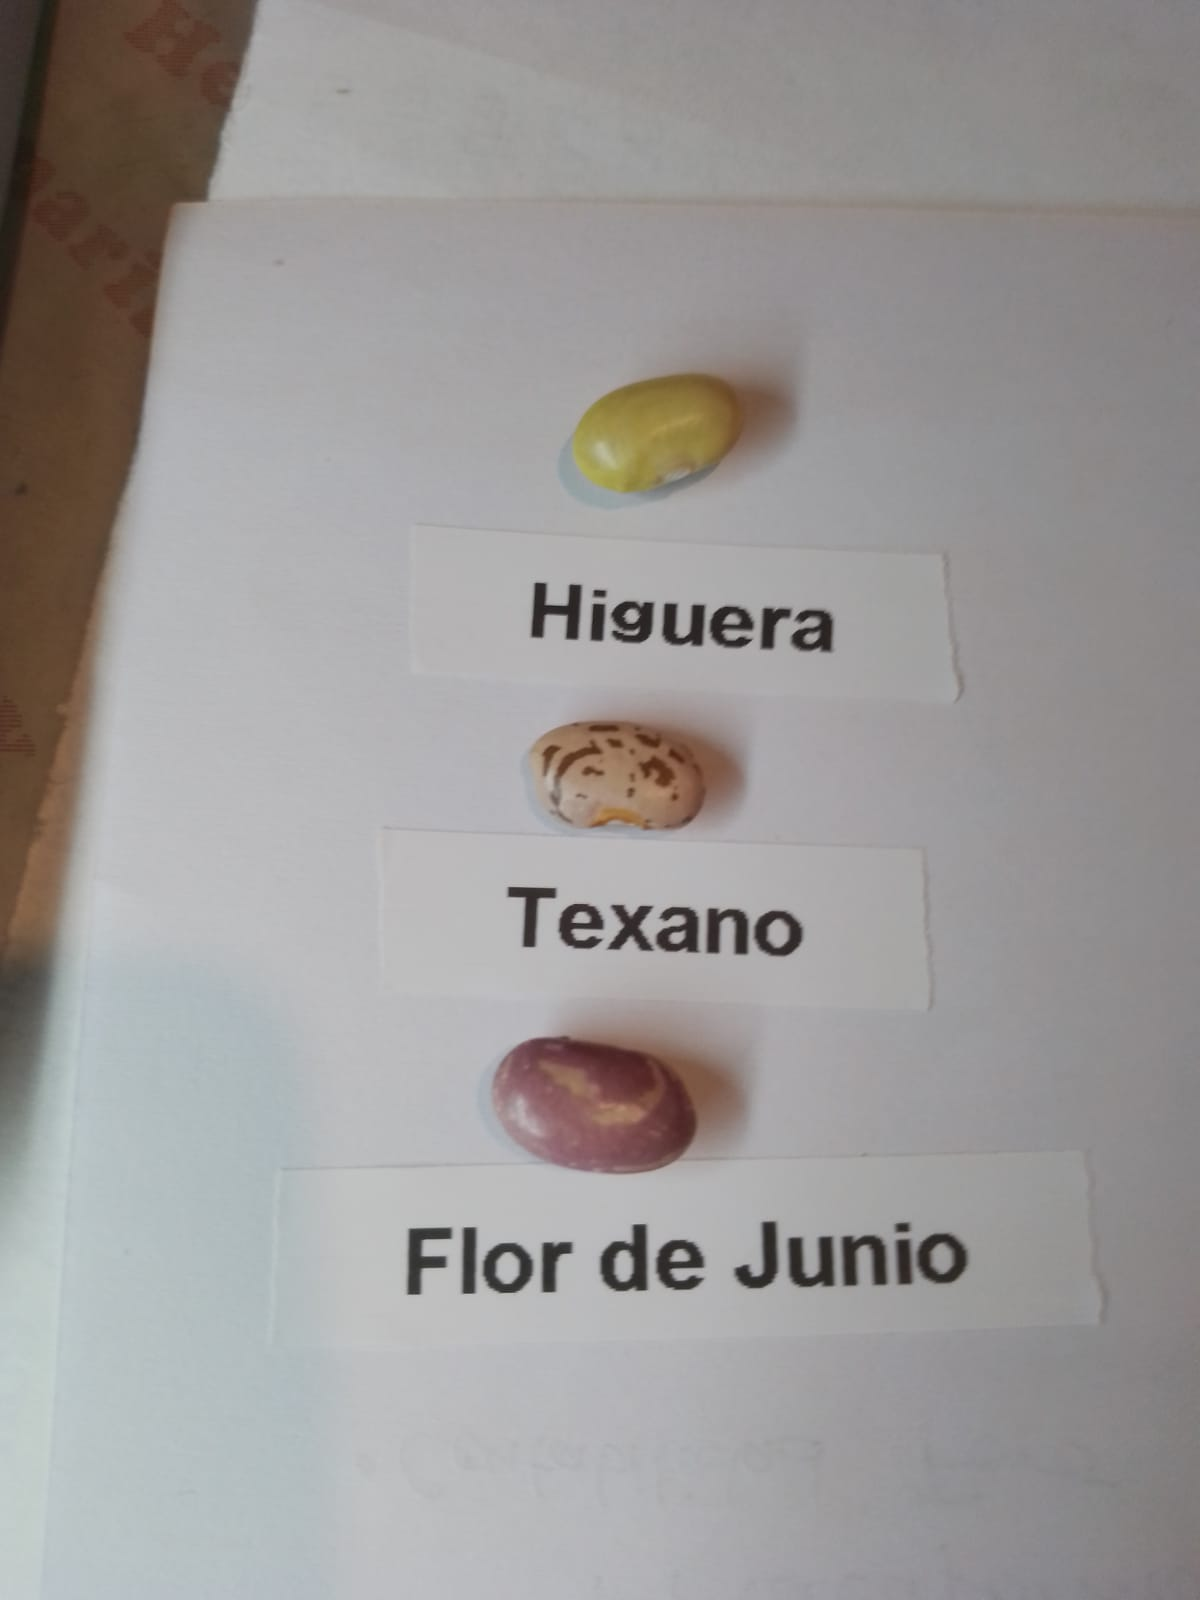

data=readtable("frijol_data.csv")

data = 10×3 table
    Var1    Var2    Var3
    ____    ____    ____

    6.81    6.04    6.85
    6.43    4.94    6.07
    6.49    4.46    5.84
    6.85     4.9    5.84
    6.63    4.54    5.61
     6.7    5.35    6.57
    6.67    4.94    5.67
    7.21    4.96       5
     6.2    4.21    6.07
    6.91    5.66    5.15


La siguiente tabla auxiliar indica el orden de mediciones

xord=readtable("frijol_orden.csv")

xord = 10×3 table
    Var1    Var2    Var3
    ____    ____    ____

      2       1       4 
      3       8       7 
      5       9      15 
      6      14      16 
     10      22      17 
     11      23      18 
     12      24      20 
     13      26      25 
     19      27      29 
     21      28      30 


data=table2array(data);
xord=table2array(xord);

## Solución

p-value = 1.348e-07
To check the ANOVA Table look at the bottom.
Reject the null hypothesis at alpha = 0.05.
There are differences between the treatments Variedad Frijol
Multiple comparison test


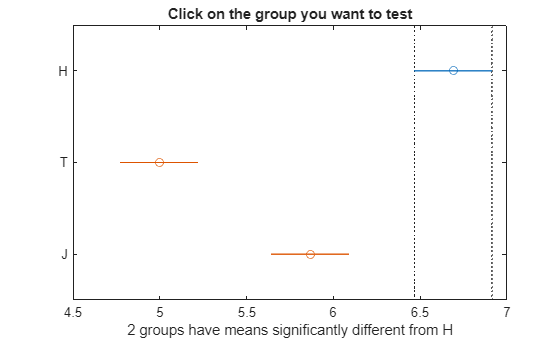

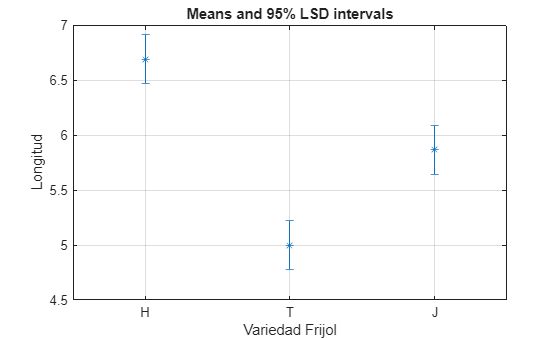

Goodness-of-fit tests
Check of independence


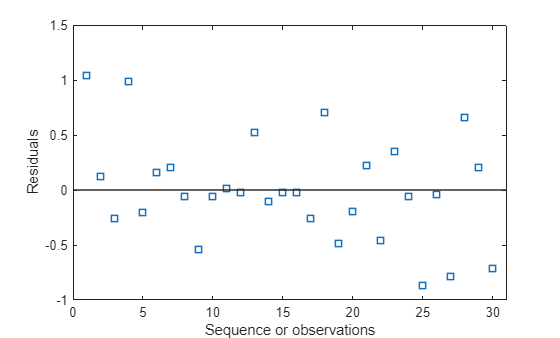

Check of Homoscedasticity


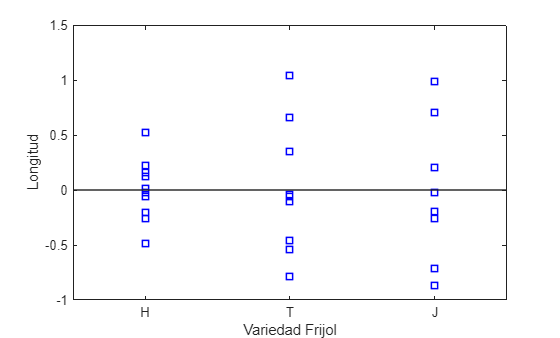

The p-value of Bartlett test = 0.1050 which is greater than alpha = 0.0500.
The assumption of homoscedasticity is satisfied.
Check of normality


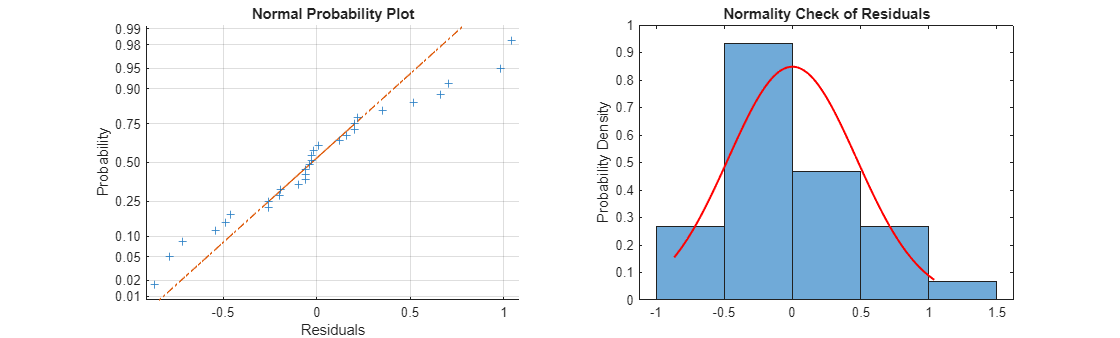

End of function monofactor


pvalue = 1.3479e-07

tablaanova = 4×6 cell array
    {'Source' }    {'SS'     }    {'df'}    {'MS'      }    {'F'       }    {'Prob>F'    }
    {'Columns'}    {[14.2837]}    {[ 2]}    {[  7.1419]}    {[ 30.0761]}    {[1.3479e-07]}
    {'Error'  }    {[ 6.4114]}    {[27]}    {[  0.2375]}    {0×0 double}    {0×0 double  }
    {'Total'  }    {[20.6951]}    {[29]}    {0×0 double}    {0×0 double}    {0×0 double  }


grupo={'H','T','J'};
alpha=0.05;
[pvalue,tablaanova]=monofactor(data,grupo,alpha,'Variedad Frijol','Longitud',xord)